% Cleanup!
clear all 
close all
clc

[MotionData]=ParseMatlabApp('onemin_twentyhz_nathan_a.mat')

MotionData = struct with fields:
            Accel: [3098×3 double]
      Orientation: [3098×3 double]
           AngVel: [3098×3 double]
          t_Accel: [3098×1 double]
    t_Orientation: [3098×1 double]
         t_AngVel: [3098×1 double]
       accel_rate: 52.6316
      orient_rate: 52.6316
      AngVel_rate: 52.6316


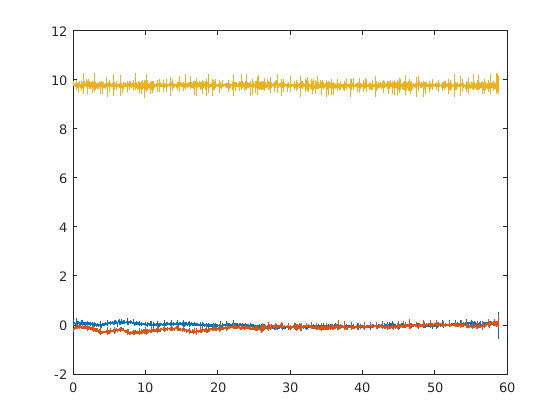

plot(MotionData.t_Accel, MotionData.Accel)

Fs = 20 %MotionData.accel_rate % in hertz

Fs = 20

N = length(MotionData.t_Accel)

N = 3098

% FIlter data into 1 minute chunk
chunk = 30 % time in seconds

chunk = 30

front_trim = 0 % trim the first ten 

front_trim = 0

index_front = round(front_trim * Fs)+1

index_front = 1

index_end = index_front + round(chunk * Fs)

index_end = 1580

MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)

MotionData = struct with fields:
            Accel: [3085×3 double]
      Orientation: [617×3 double]
           AngVel: [617×3 double]
          t_Accel: [1580×1 double]
    t_Orientation: [617×1 double]
         t_AngVel: [617×1 double]
       accel_rate: 52.6316
      orient_rate: 10.3093
      AngVel_rate: 10.3093


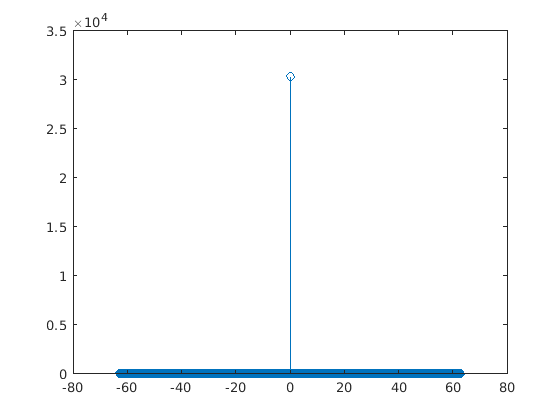

z_fft = fft(MotionData.Accel(:, 3));
z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+04 *

    3.0310
    0.0021
    0.0021
    0.0021
    0.0021


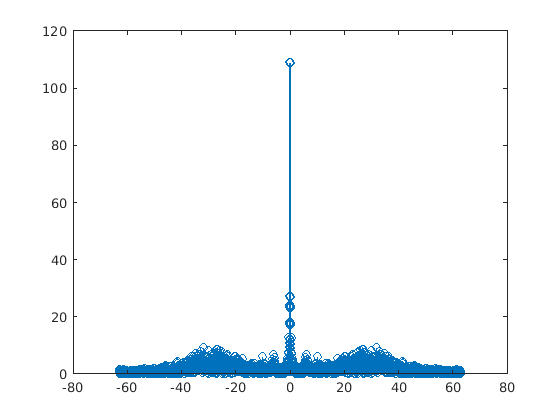

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

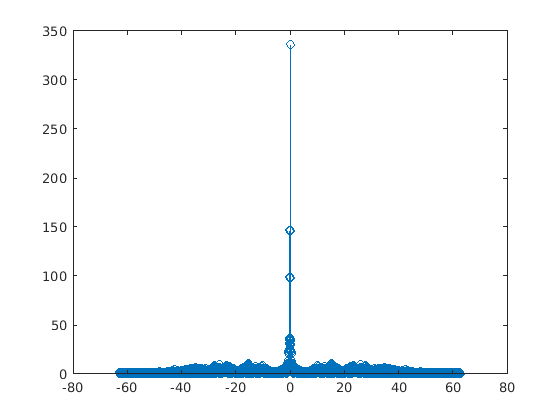

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = fftshift(y_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(y_fft_shift))